# Lengths and Masses

m_pr_cm = 0.4284/0.28;

L_tilt_vert = 0.21;
L_tilt_horz = 0.28;
L_pan_vert  = 0.207;
L_pan_horz  = 0.43;

m_tilt_vert = m_pr_cm * L_tilt_vert

m_tilt_vert = 0.3213

m_tilt_horz = m_pr_cm * L_tilt_horz

m_tilt_horz = 0.4284

m_pan_vert = m_pr_cm * L_pan_vert

m_pan_vert = 0.3167

m_pan_horz = m_pr_cm * L_pan_horz

m_pan_horz = 0.6579

# Inertia

## Tilt Axis

I_tilt = 2 * ( (1/12 * m_tilt_vert * L_tilt_vert^2) + 2 * m_tilt_horz * (L_tilt_vert/2)^2 )

I_tilt = 0.0213

## Pan Axis

Inertia of the base pan frame

I_pan_base = (1/12 * m_pan_horz * L_pan_horz^2) + 2 * m_pan_vert * (L_pan_horz/2)^2

I_pan_base = 0.0394

Inertia of the tilt system as a function of its angle

I_pan_tilt_asm_horz = @(theta_tilt) 2 * ( 1/12 * m_tilt_horz * L_tilt_horz^2 + m_tilt_horz * (L_tilt_vert * sin(theta_tilt))^2 );
I_pan_tilt_asm_vert = @(theta_tilt) 2 * ( 1/12 * m_tilt_vert * (m_tilt_vert*sin(theta_tilt))^2 ) + m_tilt_vert * (m_tilt_horz/2)^2;
I_pan_tilt_asm = @(theta_tilt) I_pan_tilt_asm_horz(theta_tilt) + I_pan_tilt_asm_vert(theta_tilt)

I_pan_tilt_asm = function_handle with value:
    @(theta_tilt)I_pan_tilt_asm_horz(theta_tilt)+I_pan_tilt_asm_vert(theta_tilt)


Adding them up!

I_pan = @(theta_tilt) I_pan_base % * I_pan_tilt_asm(theta_tilt);

I_pan = function_handle with value:
    @(theta_tilt)I_pan_base


I_pan = @(theta_tilt) I_pan_tilt_asm(theta_tilt) + I_pan_base

I_pan = function_handle with value:
    @(theta_tilt)I_pan_tilt_asm(theta_tilt)+I_pan_base


syms theta
vpa(I_pan)

$$ans = 0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512931999988813558388756064$$

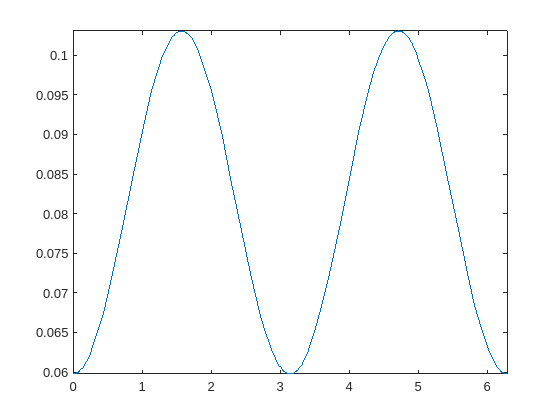

fplot(I_pan, [0, 2 * pi])